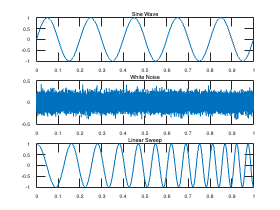

T = 1; % Duration of 1 second
A = 1; % Amplitude of 1
f0 = 5; % Start frequency of 5 Hz
f1 = 20; % Stop frequency of 20 Hz
mu = 0; % Mean of 0 for white noise
sigma = 0.1; % Standard deviation of 0.1 for white noise
fs1 = 44100; % Sampling frequency of 44.1 kHz
fs2=22500;
fs3=11500;

[sine_wave, white_noise, linear_sweep, t] = generate_signals(T, A, f0, f1, mu, sigma, fs1);
plot_signals(t, sine_wave, white_noise, linear_sweep);


% To play the signals, you can use the sound function in MATLAB:
sound(sine_wave, fs1);
pause(T);
sound(white_noise, fs1);
pause(T);
sound(linear_sweep, fs1);

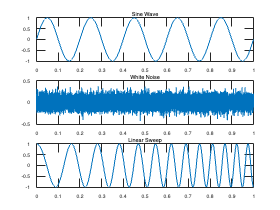

[sine_wave, white_noise, linear_sweep, t] = generate_signals(T, A, f0, f1, mu, sigma, fs2);
plot_signals(t, sine_wave, white_noise, linear_sweep);


% To play the signals, you can use the sound function in MATLAB:
sound(sine_wave, fs2);
pause(T);
sound(white_noise, fs2);
pause(T);
sound(linear_sweep, fs2);

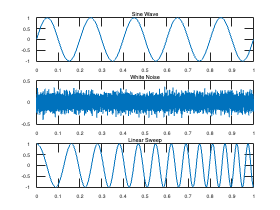

[sine_wave, white_noise, linear_sweep, t] = generate_signals(T, A, f0, f1, mu, sigma, fs3);
plot_signals(t, sine_wave, white_noise, linear_sweep);


% To play the signals, you can use the sound function in MATLAB:
sound(sine_wave, fs3);
pause(T);
sound(white_noise, fs3);
pause(T);
sound(linear_sweep, fs3);


%
%Lorsque la fréquence d'échantillonnage diminue, 
% la gamme des fréquences sonores pouvant être enregistrées 
% et reproduites avec précision est également réduite. 
% Cela affecte la clarté et le détail du son, 
% en particulier dans les hautes fréquences. 
% Les fréquences d'échantillonnage plus élevées préservent mieux la fidélité du 
% signal analogique original,
% tandis que les fréquences d'échantillonnage plus basses peuvent entraîner une dégradation
% de la qualité du son en raison de l'impossibilité d'enregistrer les informations à haute fréquence. 
% Dans la pratique, le choix de la fréquence d'échantillonnage nécessite un compromis entre 
% la taille du fichier et la qualité du son.